# Experiment 2_1

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

### Part 1: Convolution

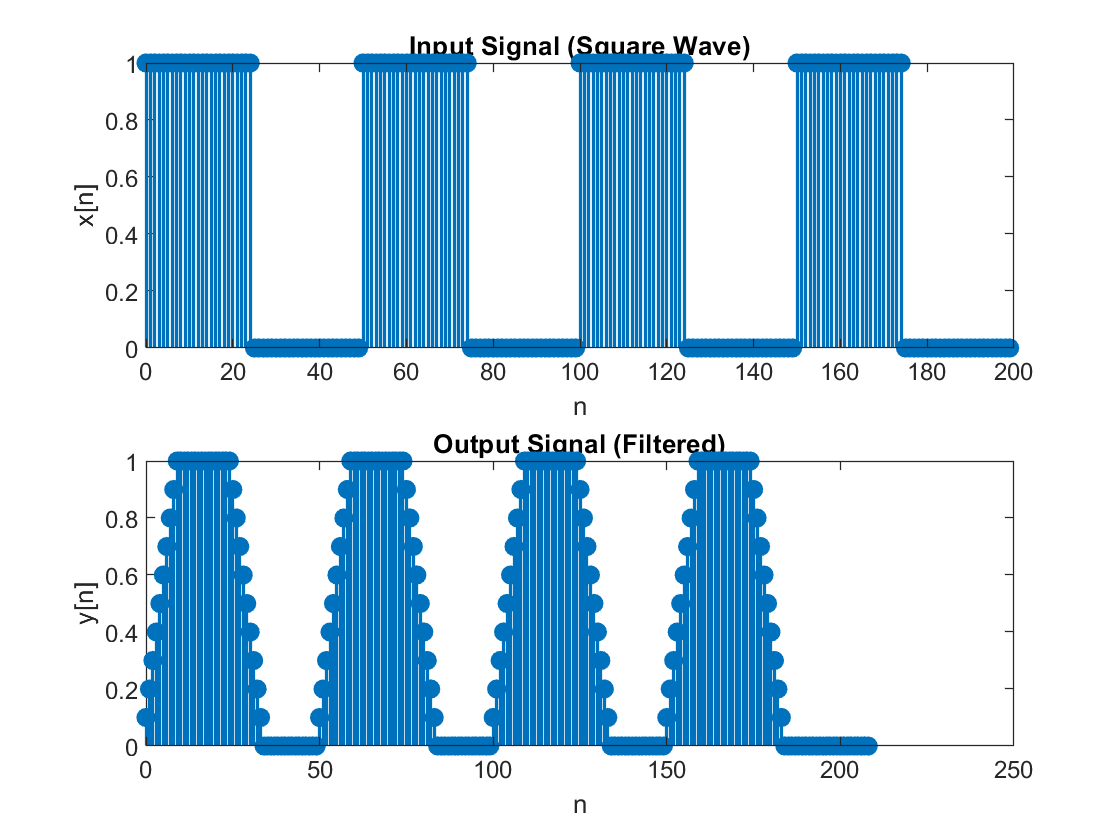

%% Part 2-1-2
L = 200;
K = 50;

t = 0:(L-1);
x = double(mod(t, K) < (K/2)); 

h = 0.1 * ones(1, 10);

y = myconv(h, x);

figure("Name","Convolution part 2-1-2");
subplot(2,1,1);
stem(t, x, 'filled', 'LineWidth', 1.2);
title('Input Signal (Square Wave)');
xlabel('n');
ylabel('x[n]');

t_y = 0:length(y)-1;
subplot(2,1,2);
stem(t_y, y, 'filled', 'LineWidth', 1.2);
title('Output Signal (Filtered)');
xlabel('n');
ylabel('y[n]');

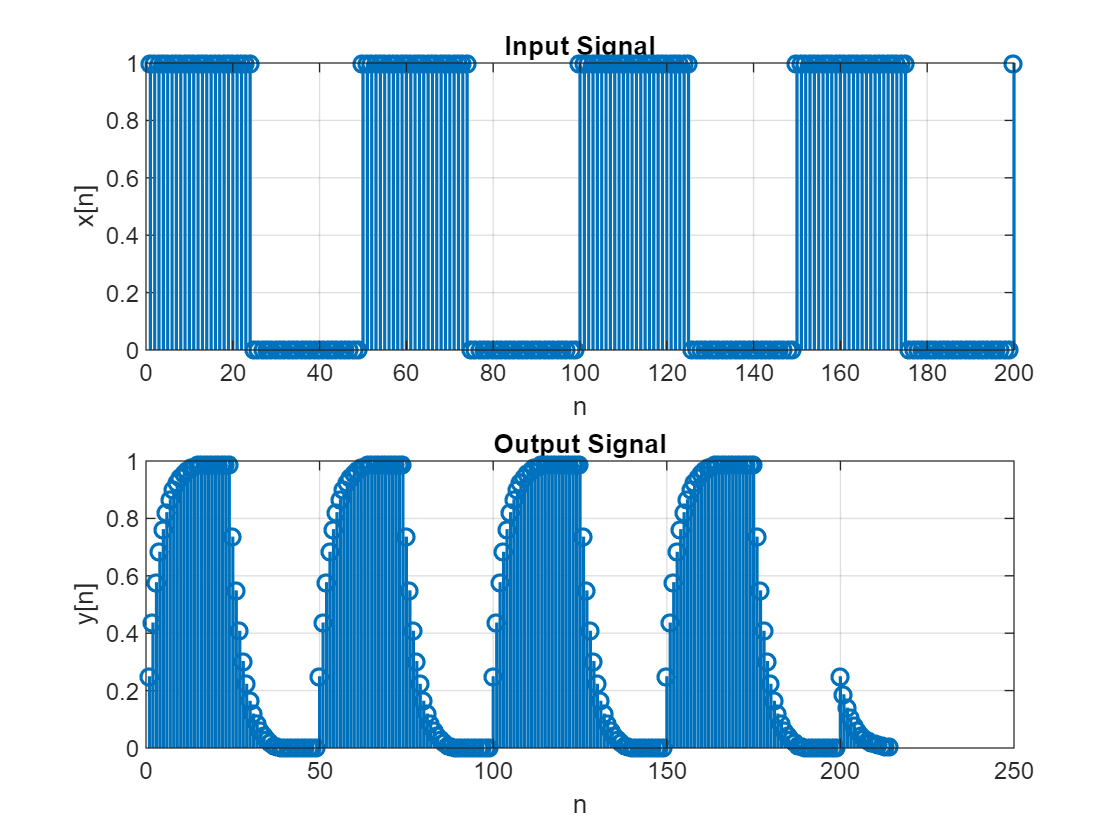

% Part 2-1-3
M = 14; 
L = 200; 
K = 50; 
x = (square(2 * pi * (1:L) / K) + 1) / 2;
h2 = zeros(1, M+1); 
for n = 1:M+1
    h2(n) = 0.25 * (0.75)^(n-1); 
end

y = myconv(h2, x);

figure("Name","Convolution part 2-1-3");
subplot(2, 1, 1);
stem(x, 'LineWidth', 1.2);
title('Input Signal');
xlabel('n');
ylabel('x[n]');
grid on;

subplot(2, 1, 2);
stem(y, 'LineWidth', 1.2);
title('Output Signal');
xlabel('n');
ylabel('y[n]');
grid on;

% Part 2-1-4
h3 = (1/5) * [1 -5 10 -10 5 -1]; 

y = myconv(h3, x);

figure("Name","Convolution part 2-1-4");
subplot(2, 1, 1);
bar(x);
hold on;
plot(1:length(x), x, 'o', 'MarkerSize', 4, 'MarkerFaceColor', 'b'); 
hold off;
title('Input Signal');
xlabel('n');
ylabel('x[n]');
grid on;


subplot(2, 1, 2);
bar(y); 
hold on;
plot(1:length(y), y, 'o', 'MarkerSize', 4, 'MarkerFaceColor', 'b'); 
hold off;
title('Output Signal');
xlabel('n');
ylabel('y[n]');
grid on;

### Part 2: Filter design

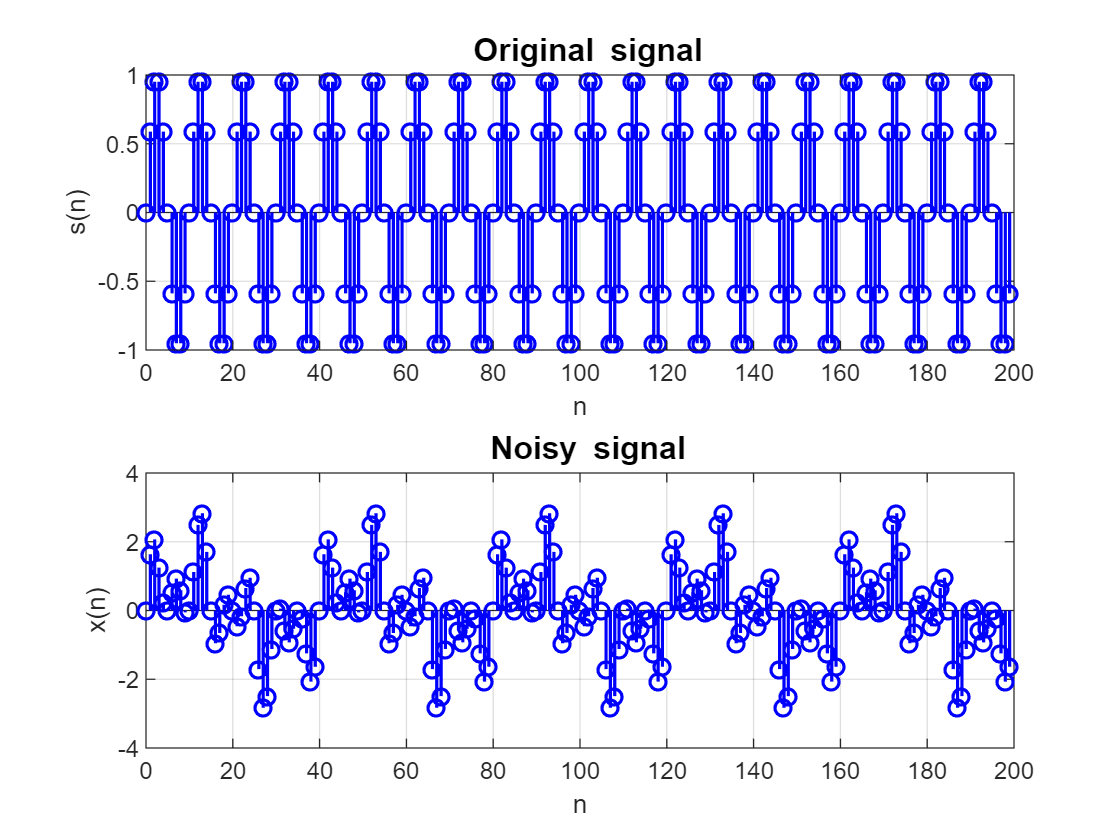

% Part 2-2-1
w1=0.05*pi;
w2=0.2*pi;
w3=0.35*pi;

L = 200;
s = sin(w2* (0:L-1));
v = sin(w1* (0:L-1)) + sin(w3* (0:L-1)); 
x_sum = s + v; 


% Plot original signal
subplot(2,1,1); 
stem(0:L-1, s, 'b', 'LineWidth', 1.2);
title('\bf Original signal', 'FontSize', 12);
xlabel('n');
ylabel('s(n)');
grid on;

% Plot noisy signal
subplot(2,1,2); 
stem(0:L-1, x_sum, 'b', 'LineWidth', 1.2);
title('\bf Noisy signal', 'FontSize', 12);
xlabel('n');
ylabel('x(n)');
grid on;

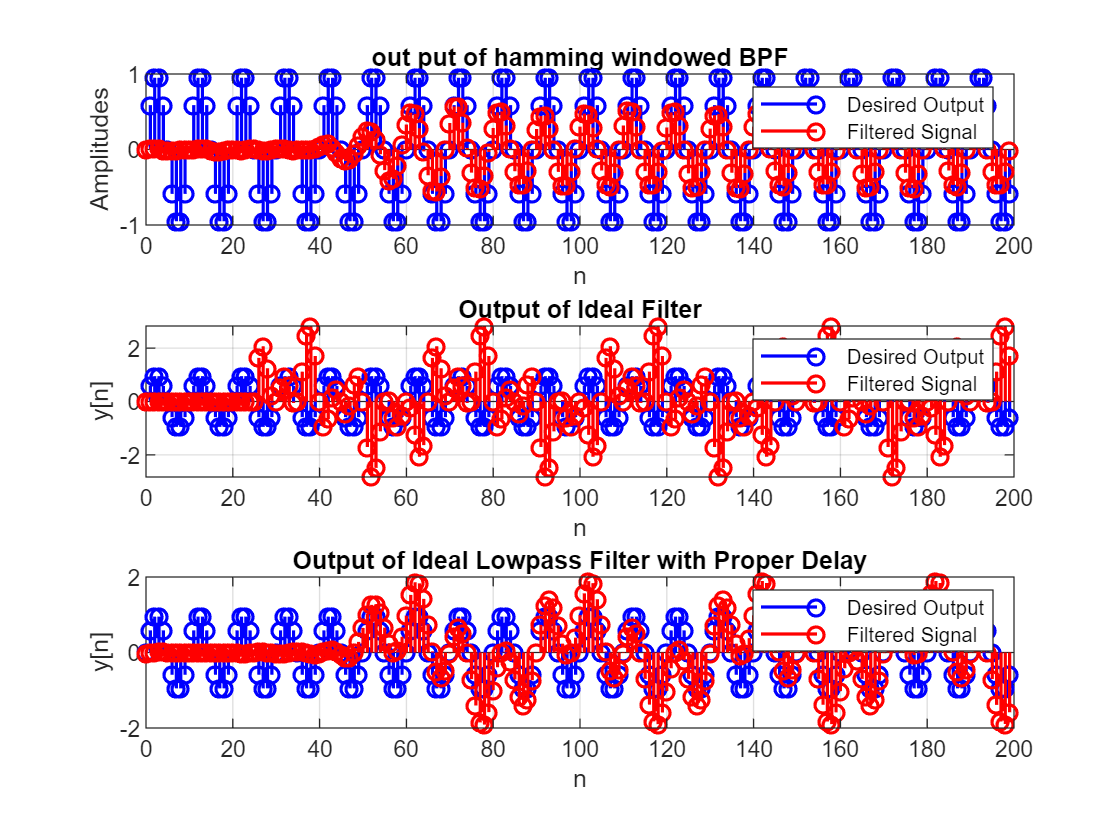

% Part 2-2-2

% Parameters for hamming window 
M = 100; 
wa = 0.15; % Lower cutoff frequency
wb = 0.25; % Upper cutoff frequency

w = 0.54 - 0.46 * sin(2 * pi * (0:M) / M); % Hamming window
h = zeros(1, M+1); 

for n = 1:M+1
    h(n) = w(n) * (wb*sinc((wb * (n - M/2))) - wa*sinc((wa * (n -M/2))));
end

y = filter(h, 1, x_sum); 

figure;
subplot(3,1,1)
stem(0:L-1, s, 'b', 'DisplayName', 'Desired Output', 'LineWidth', 1.2);
hold on;
stem(0:L-1, y, 'r', 'DisplayName', 'Filtered Signal', 'LineWidth', 1.2); 
title('out put of hamming windowed BPF');
xlabel('n');
ylabel('Amplitudes');
legend; 
grid on;

% Parameters forIdeal Filter 
fc = 2; 
N = 51;  
n = -(N-1)/2 : (N-1)/2;  
h = 2 * fc * sinc(2 * fc * n);  
h = h / sum(h); 

y_ideal = filter(h, 1, x_sum);  

subplot(3,1,2)
stem(0:L-1, s, 'b', 'DisplayName', 'Desired Output', 'LineWidth', 1.2);
hold on;
stem(0:L-1, y_ideal, 'r', 'DisplayName', 'Filtered Signal', 'LineWidth', 1.2); 
title('Output of Ideal Filter');
xlabel('n');
ylabel('y[n]');
legend; 
grid on;


% Parameters
M = 100; 
wc = 0.25 * pi; % Cutoff frequency (normalized)
delay = M / 2; % Ideal delay to center the filter

n = -M:M; % Time index (centered for symmetry)

% Ideal lowpass filter using sinc function with delay correction
h_ideal = (wc/pi) * sinc(wc * (n - delay) / pi);

% Apply the filter using convolution
y_ideal = conv(x_sum, h_ideal, 'same');

subplot(3,1,3)
stem(0:L-1, s, 'b', 'DisplayName', 'Desired Output', 'LineWidth', 1.2);
hold on;
stem(0:L-1, y_ideal, 'r', 'DisplayName', 'Filtered Signal', 'LineWidth', 1.2); 
title('Output of Ideal Lowpass Filter with Proper Delay');
xlabel('n');
ylabel('y[n]');
legend;
grid on;

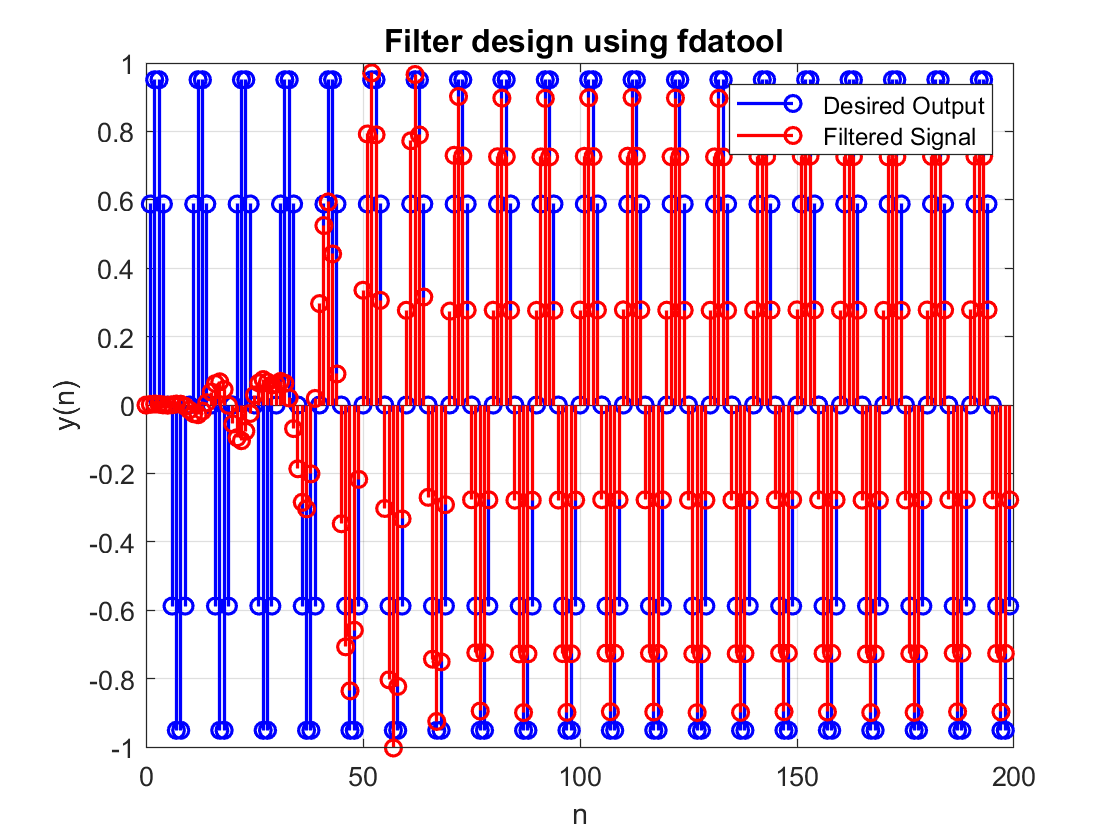

% Part 2-2-3
% The filter is already designed using the FDATOOL and here just load the coefficients

coeff = load("filter_coefficients.mat").coeff;
fda_fil = filter(coeff , 1 , x_sum);

% Plot original signal
figure;
stem(0:L-1, s, 'b', 'LineWidth', 1.2, 'DisplayName', 'Desired Output');
title('\bf Filter design using fdatool', 'FontSize', 12);
xlabel('n');
ylabel('s(n)');
grid on;
hold on;
stem(0:L-1, fda_fil, 'r', 'LineWidth', 1.2, 'DisplayName', 'Filtered Signal');
grid on;
xlabel("n");
ylabel("y(n)");
legend;

Part 2-1-1 function

% function y = myconv(h, x)
%     % h: Filter or impulse response
%     % x: Input signal
%     % y: Result of the convolution
%     % Lengths of the filter and the signal
%     M = length(h) - 1;
%     L = length(x) - 1;
%     y_length = M + L - 1;
%     y = zeros(1, y_length);
%     % Perform the convolution calculation
%     for n = 1:y_length
%         m_min = max(0, n - L);
%         m_max = min(M, n - 1);
%         for m = m_min:m_max
%             y(n) = y(n) + h(m + 1) * x(n - m);
%         end
%     end
% end

function y = myconv(h, x)
    Lx = length(x);
    Lh = length(h);
    Ly = Lx + Lh - 1;

    h_flipped = fliplr(h);

    % Zero-pad both sequences to length Ly
    x_padded = [zeros(1, Ly - Lx), x];
    h_padded = [h_flipped, zeros(1, Ly - Lh)];

    y = zeros(1, Ly);

    % Perform convolution using single loop and circshift
    for n = 1:Ly
        h_shifted = circshift(h_padded, [0, n - 1]);
        y(n) = sum(h_shifted .* x_padded);
    end
end